# Analysis of parameter variation

load newBattery.mat;
load ukfBatteryParams.mat;
names = ['a', 'b', 'c'];
u = 1;

### Analysis of parameter variation

determine the affect of altering various battery parameters 

- Increasing R0

disp(battery.R0);

    0.0011



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    ros.(names(i)) = battery.R0;
    battery.R0 = battery.R0 * 10;
end
battery.R0 = ros.a;
disp(battery.R0);

    0.0011



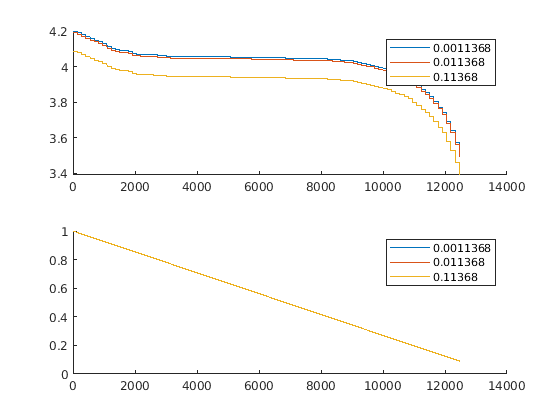


f1 = figure(1); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(ros.a), num2str(ros.b), num2str(ros.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(ros.a), num2str(ros.b), num2str(ros.c));

Changing R0 changes the output voltage, but the voltage curve and the SOC are unaffected. 

- Decrease Q

disp(battery.Q);

    3.8000



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    qs.(names(i)) = battery.Q;
    battery.Q = battery.Q * .9;
end
battery.Q = qs.a;
disp(battery.Q);

    3.8000



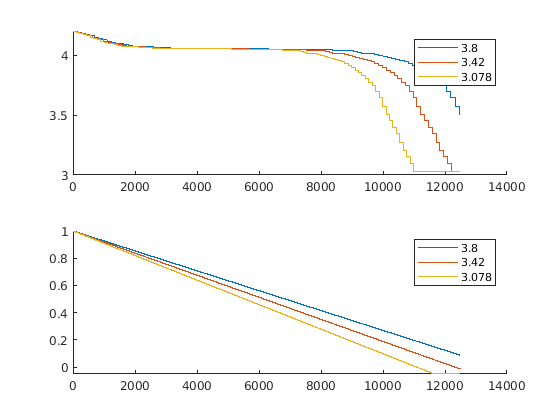


f2 = figure(2); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

Decreasing Q decreases the battery capacity and SOC slope

- Decrease coulombic efficiency by increasing battery.n

disp(battery.n);

    0.9987



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    qs.(names(i)) = battery.n;
    battery.n = battery.n * 1.1;
end
battery.n = qs.a;
disp(battery.n);

    0.9987



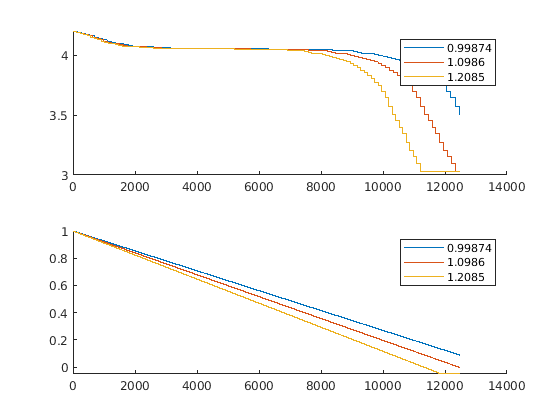


f2 = figure(2); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

Altering coloumbic efficieny results in similar behavior to altering capacity

- increasing battery.R ( the resistor in the R-C pair)

disp(battery.R);

   2.8283e-04



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    qs.(names(i)) = battery.R;
    battery.R = battery.R * 25;
end
battery.R = qs.a;
disp(battery.R);

   2.8283e-04



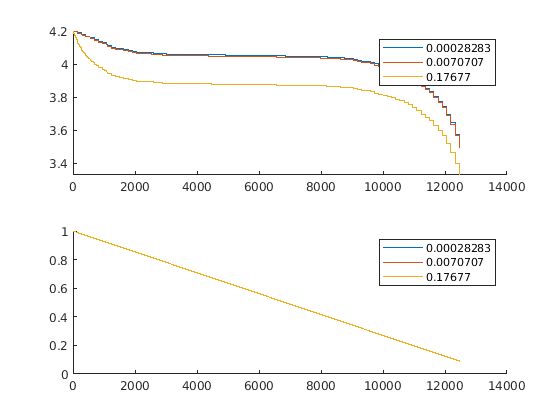


f2 = figure(2); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

Increasing R affects the voltage curve, but not the SOC slope

- Altering battery.RC (the capacitor in the R-C pair)

disp(battery.RC);

    3.6572



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    qs.(names(i)) = battery.RC;
    battery.RC = battery.RC / 20;
end
battery.RC = qs.a;
disp(battery.RC);

    3.6572



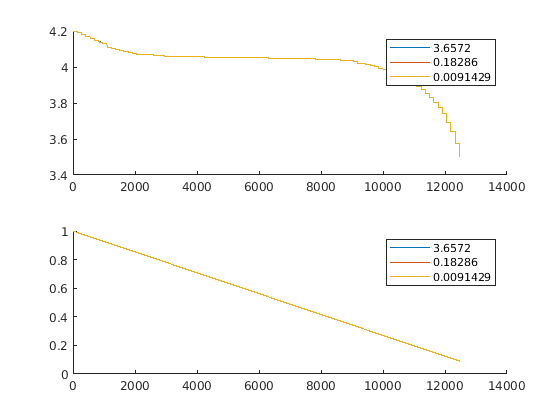


f2 = figure(2); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

Changing this parameter does not alter the SOC slope or voltage curve

- Degrade R0, R, and Q at the same time

disp(battery.R);

   2.8283e-04



disp(battery.R0);

    0.0011



disp(battery.Q);

    3.8000



for i = 1:3
    simout = sim('batteryMine');
    voltages.(names(i)) = simout.voltage.Data;
    socs.(names(i)) = simout.soc.Data;
    rs.(names(i)) = battery.R;
    r0s.(names(i)) = battery.R0;
    qs.(names(i)) = battery.Q;
    battery.R = battery.R * 25;
    battery.R0 = battery.R0 * 10;
    battery.Q = battery.Q * .9;
end
battery.R = rs.a;
battery.R0 = r0s.a;
battery.Q = qs.a;
disp(battery.R);

   2.8283e-04



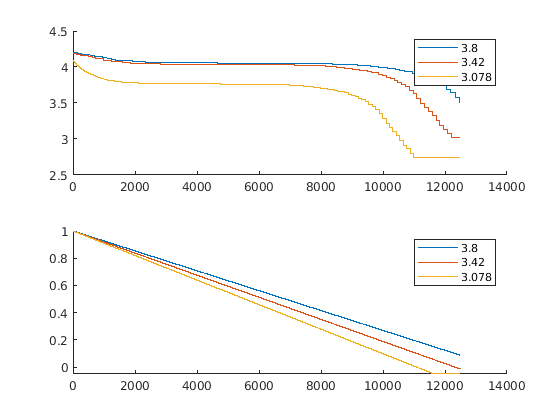


f2 = figure(2); clf;
subplot(2,1,1);
hold on;
plot(voltages.a);
plot(voltages.b);
plot(voltages.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));

subplot(2,1,2);
hold on;
plot(socs.a);
plot(socs.b);
plot(socs.c);
hold off;
legend(num2str(qs.a), num2str(qs.b), num2str(qs.c));